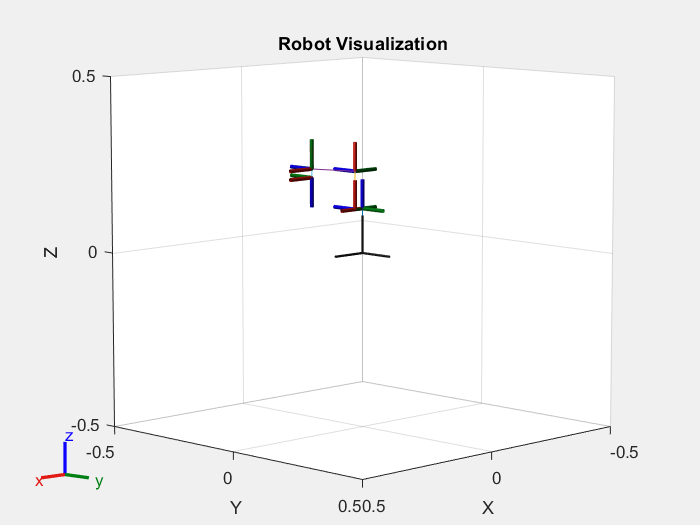

clc;
clear all;

% Create a rigid body tree model for the robot
robot = rigidBodyTree('DataFormat', 'column');

% Define rigid bodies
arm1 = rigidBody("arm1");
arm2 = rigidBody("arm2");
arm3 = rigidBody("arm3");
arm4 = rigidBody("arm4");
arm5 = rigidBody("arm5");
arm6 = rigidBody("arm6");

% Define collision objects for each part
collisionBox1 = collisionCylinder(0.08, 0.1); 
collisionBox2 = collisionCylinder(0.04, 0.127);
collisionBox3 = collisionBox(0.108, 0.02969, 0.02969);
collisionBox4 = collisionCylinder(0.02, 0.04); 
collisionBox5 = collisionCylinder(0.02, 0.16898); 
collisionBox6 = collisionCylinder(0.02, 0.04); 
collisionBox7 = collisionCylinder(0.01, 0.02429); 

% Define transformations for collision objects
tform1 = trvec2tform([0, 0, +0.05]);
tform2 = trvec2tform([0, 0, -0.127 / 2]);
tform3 = trvec2tform([0.108 / 2, 0, 0]);
tform4 = trvec2tform([0, 0, 0]);
tform5 = trvec2tform([0, 0, -0.16898 / 2]);
tform6 = trvec2tform([0, 0, 0]);
tform7 = trvec2tform([0, 0, 0]);

% Add collision objects to the rigid bodies
addCollision(robot.Base, collisionBox1, tform1);
addCollision(arm1, collisionBox2, tform2);
addCollision(arm2, collisionBox3, tform3);
addCollision(arm3, collisionBox4, tform4);
addCollision(arm4, collisionBox5, tform5);
addCollision(arm5, collisionBox6, tform6);
addCollision(arm6, collisionBox7, tform7);

% Define joints
jnt1 = rigidBodyJoint("jnt1", "revolute");
jnt2 = rigidBodyJoint("jnt2", "revolute");
jnt3 = rigidBodyJoint("jnt3", "revolute");
jnt4 = rigidBodyJoint("jnt4", "revolute");
jnt5 = rigidBodyJoint("jnt5", "revolute");
jnt6 = rigidBodyJoint("jnt6", "revolute");

% Define DH parameters this one may have some problems
% dhparams = [
%     0        0        0.127   0;
%     0.02969  pi/2     0       0;
%     0.108    0        0       0;
%     0.020   -pi/2     0.16898 0;
%     0        pi/2     0       pi/2;
%     0        pi/2     0.02429 0
% ];

dhparams = [
    0,        0,        0.127,       0;
    0.02969,       pi/2,     0,        0;
    0.108,       0,        0,        0;
    0.020,       pi/2,     0.16898,       0;
    0,       -pi/2,     0,        0;
    0,        pi/2,     0.02429,       0;
    ];

% Add rigid bodies and joints to the robot
bodies = {arm1, arm2, arm3, arm4, arm5, arm6};
joints = {jnt1, jnt2, jnt3, jnt4, jnt5, jnt6};
for i = 1:numel(bodies)
    setFixedTransform(joints{i}, dhparams(i, :), "mdh");
    bodies{i}.Joint = joints{i};
    if i == 1
        addBody(robot, bodies{i}, robot.Base.Name);
    else
        addBody(robot, bodies{i}, bodies{i - 1}.Name);
    end
end

% Visualize the robot in its home configuration
homeconfig = [0; pi/2; 0; 0; -pi/2; 0];

figure;
show(robot, homeconfig, "Collisions", "off");
title('Robot Visualization');




% Define symbolic variables for Jacobian and trajectory computation
syms theta1 theta2 theta3 theta4 theta5 theta6 real
joint_angles = [theta1; theta2; theta3; theta4; theta5; theta6];

% Forward kinematics computation
T = eye(4);
for i = 1:numel(joint_angles)
    a = dhparams(i, 1);
    alpha = dhparams(i, 2);
    d = dhparams(i, 3);
    theta = joint_angles(i);
    Ti = [
        cos(theta), -sin(theta), 0, a;
        sin(theta) * cos(alpha), cos(theta) * cos(alpha), -sin(alpha), -sin(alpha) * d;
        sin(theta) * sin(alpha), cos(theta) * sin(alpha), cos(alpha), cos(alpha) * d;
        0, 0, 0, 1
    ];
    T = T * Ti;
   
end

T06_sym = simplify(T);
Q_t = T06_sym(1:3, 4); % extract position

R_t=reshape(T06_sym(1:3, 1:3), [], 1); % Extract rotation matrix a make it a column vector

%Desired rotation matrix(Z-axix of end point perpendicular to sagittal plane)
R_target=[1,0,0;
        0,0,-1;
        0,1,0];
R_target = reshape(R_target, [], 1);



% Jacobian matrices
J_translation = jacobian(Q_t, joint_angles);
J_orientation = jacobian(R_t, joint_angles);
J = [J_translation; J_orientation];

% limits:
% Define joint limits and velocity limits
joint_limits = [
    deg2rad(-110), deg2rad(160);  
    pi/2+ deg2rad(-35), pi/2+ deg2rad(70);    
    deg2rad(-120), deg2rad(60);   
    deg2rad(-180), deg2rad(180);  
    deg2rad(-200) - pi/2, deg2rad(30) - pi/2   
    deg2rad(-360), deg2rad(360)  
];
 


joint_velocities = [
    deg2rad(85);  
    deg2rad(60);  
    deg2rad(65);  
    deg2rad(200); 
    deg2rad(200); 
    deg2rad(450)  
];



%poses:
PH = double(subs(Q_t, joint_angles, homeconfig))'; % Home position
PA = [0.200, 0.0, 0.330];
PB = [0.200, -0.200, 0.080];
PC = [0.200, 0.200, 0.120];
P0 = [0.150, 0.0, 0.330];
P1 = [0.150, -0.200, 0.080];
P2 = [0.150, 0.200, 0.120];


% Waypoints and Total Parameters
waypoints = [PH; PA; P0; PA; PB; P1; PB; PC; P2; PC; PH; PA; P0];
n_points_total = 500; % Total number of steps
total_time = 20; % Total time for the trajectory
dt_steps= total_time/(n_points_total - 1);

% 1. Calculate Segment Distances
num_segments = 12;
segment_distances = zeros(1, num_segments);
for i = 1:num_segments
    segment_distances(i) = norm( waypoints(i+1, :) - waypoints(i, :) ); % Euclidean distance
end

% 2. Proportional Distribution of Steps and Time
total_distance = sum(segment_distances);
proportional_time = total_time * (segment_distances / total_distance); % Proportional time
t_keyframes = [0, cumsum(proportional_time)]; % Updated keyframes for each waypoint

% 3. Generate Fine Time Array
t = linspace(0, total_time, n_points_total); % Uniform time grid over 10 seconds

% 4. Generate Trajectories Using interp1
x_traj = interp1(t_keyframes, waypoints(:, 1), t); % Interpolated X trajectory
y_traj = interp1(t_keyframes, waypoints(:, 2), t); % Interpolated Y trajectory
z_traj = interp1(t_keyframes, waypoints(:, 3), t); % Interpolated Z trajectory

% Combine into Cartesian trajectory
cartesian_traj = [x_traj; y_traj; z_traj];


% Define keyframes for the angle (psi) for PH → PA → P0
           %      H    A     0    A    B     1         B     C     2     C      H    A      0             
psi_keyframes = [pi, (pi+pi/2),(pi+pi/2),(pi+pi/2),(pi-pi/2),(pi-pi/2),(pi-pi/2),(pi+pi/2),(pi+pi/2),(pi+pi/2),pi,(pi+pi/2),(pi+pi/2)];

% Interpolate psi for all time steps using linear interpolation
psi_interpolated = interp1(t_keyframes, psi_keyframes, t, 'linear'); % Linear interpolation of angles

% Generate rotation matrices for each time step
R_interpolated = zeros(9, length(t)); % Preallocate flattened rotation matrices
for k = 1:length(t)
    % Rebuild the rotation matrix for the current angle
    psi = psi_interpolated(k);
    R_interp = [
        1,  0,           0;
        0,  cos(psi),   -sin(psi);
        0,  sin(psi),    cos(psi)
    ];
    R_interpolated(:, k) = reshape(R_interp, [], 1); % Flatten the matrix
end

%here we have achieved the interpolation of the matrix

%______________________________________________________________________

% Initialize joint trajectory
joint_trajectory = zeros(6, length(t));
joint_trajectory(:, 1) = homeconfig;

% Newton-Raphson inverse kinematics
max_iterations = 100;

for k = 2:length(t)

     disp(['k: ', num2str(k)]);

    % Extract position and orientation target for this timestep
    p_target = cartesian_traj(:, k); % Position target
    R_target = R_interpolated(:, k); % Orientation target

    % Initial guess for joint angles = (previous timestep result)
    theta_k = joint_trajectory(:, k - 1); % starting from homeconfig
    
    % Deploy Newton-Raphson
    for iter = 1:max_iterations

        % Evaluating Q_t and position error
        Q_k = double(subs(Q_t, joint_angles, theta_k));
        position_error = p_target - Q_k;

        % Evaluating R_t and orientation error
        R_K = double(subs(R_t, joint_angles, theta_k));
        orientation_error = R_target - R_K;

        % Combine them and evaluate the combined Jacobian
        combined_error = [position_error; orientation_error];

         % Compute the combined Jacobian
        J_trans = double(subs(J_translation, joint_angles, theta_k)); % Translational Jacobian
        J_rot = double(subs(J_orientation, joint_angles, theta_k)); % Rotational Jacobian
        J_combined = [J_trans; J_rot]; % Combined Jacobian

        % Check for singularities
        cond_number = cond(J_combined);
        if cond_number > 1e12
            warning('Jacobian is near-singular at timestep %d, iteration %d', k, iter);
            break;
        end

        J_inv = pinv(J_combined); % Direct inverse (assumes Jacobian is square and invertible)

        % Compute the change in joint angles
        delta_theta = J_inv * combined_error;

        
        % Limit the step size change to the max allowed by the velocities
        % (already element-wise...row by row)
        %with this implementation though...im clamping each iteration...but
        %summing the contribute of each ieteration I can exceed.
        max_delta_theta = joint_velocities * dt_steps; % Maximum allowed change per joint
        delta_theta = max(min(delta_theta, max_delta_theta), -max_delta_theta); % Clamp delta_theta
        
        % Update the joint angles
        theta_k = theta_k + delta_theta;

        % Exit condition: check if the error is below tolerance
        if norm(combined_error) < 1e-2
            break;
        end

        % If maximum iterations are reached, issue a warning
        if iter == max_iterations
            warning('Newton-Raphson did not converge at timestep %d', k);
        end
    end
    
    %   % Check joint limits
    % for joint_idx = 1:size(joint_limits, 1)
    %     if theta_k(joint_idx) < joint_limits(joint_idx, 1) || theta_k(joint_idx) > joint_limits(joint_idx, 2)
    %         fprintf('Warning: Joint %d exceeds limits at timestep %d. Angle: %.2f rad\n', ...
    %             joint_idx, k, theta_k(joint_idx));
    %     end
    % end

    % % Check joint velocity limits
    % joint_velocity = abs((theta_k - joint_trajectory(:, k - 1)) / (t(k) - t(k - 1)));
    % for joint_idx = 1:size(joint_velocities, 1)
    %     if joint_velocity(joint_idx) > joint_velocities(joint_idx)
    %         fprintf('Warning: Joint %d exceeds velocity limit at timestep %d. Velocity: %.2f rad/s\n', ...
    %             joint_idx, k, joint_velocity(joint_idx));
    %     end
    % end

    % Store the guessed angles in the trajectory array
    joint_trajectory(:, k) = theta_k;
end

k: 2
k: 3
k: 4
k: 5
k: 6
k: 7
k: 8
k: 9
k: 10
k: 11
k: 12
k: 13
k: 14
k: 15
k: 16
k: 17
k: 18
k: 19
k: 20
k: 21
k: 22
k: 23
k: 24
k: 25
k: 26
k: 27
k: 28
k: 29
k: 30
k: 31
k: 32
k: 33
k: 34
k: 35
k: 36
k: 37
k: 38
k: 39
k: 40
k: 41
k: 42
k: 43
k: 44
k: 45
k: 46
k: 47
k: 48
k: 49
k: 50
k: 51
k: 52
k: 53
k: 54
k: 55
k: 56
k: 57
k: 58
k: 59
k: 60
k: 61
k: 62
k: 63
k: 64
k: 65
k: 66
k: 67
k: 68
k: 69
k: 70
k: 71
k: 72
k: 73
k: 74
k: 75
k: 76
k: 77
k: 78
k: 79
k: 80
k: 81
k: 82
k: 83
k: 84
k: 85
k: 86
k: 87
k: 88
k: 89
k: 90
k: 91
k: 92
k: 93
k: 94
k: 95
k: 96
k: 97
k: 98
k: 99
k: 100
k: 101
k: 102
k: 103
k: 104
k: 105
k: 106
k: 107
k: 108
k: 109
k: 110
k: 111
k: 112
k: 113
k: 114
k: 115
k: 116
k: 117
k: 118
k: 119
k: 120
k: 121
k: 122
k: 123
k: 124
k: 125
k: 126
k: 127
k: 128
k: 129
k: 130
k: 131
k: 132
k: 133
k: 134
k: 135
k: 136
k: 137
k: 138
k: 139
k: 140
k: 141
k: 142
k: 143
k: 144
k: 145
k: 146
k: 147
k: 148
k: 149
k: 150
k: 151
k: 152
k: 153
k: 154
k: 155
k: 156
k: 157
k: 158
k: 159


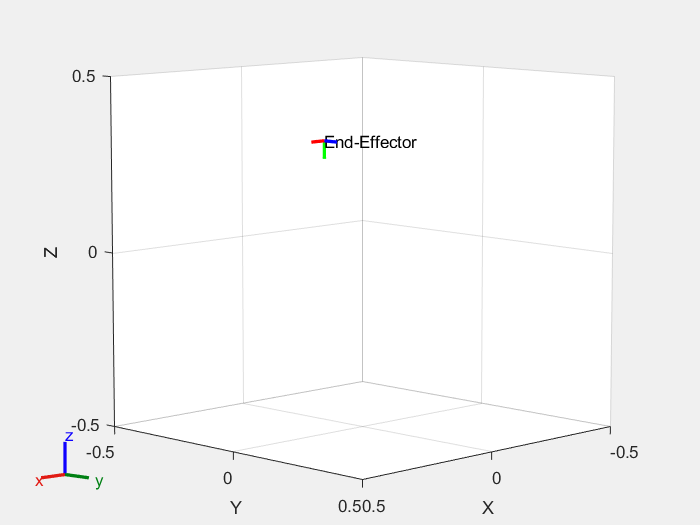



% Visualize motion of end effector only
for i = 1:length(t)
    % Show the robot without displaying all frames
    show(robot, joint_trajectory(:, i), "Collisions", "off", "Frames", "off", "PreservePlot", false);
    hold on;
    
    % Get the end-effector transformation matrix
    T_ee = getTransform(robot, joint_trajectory(:, i), "arm6");
    
    % Extract position of the end-effector
    ee_position = T_ee(1:3, 4); % Extract translation vector

    % Extract orientation (rotation matrix)
    R_ee = T_ee(1:3, 1:3); % Extract rotation matrix

    % Plot the end-effector frame axes
    quiver3(ee_position(1), ee_position(2), ee_position(3), ...
            R_ee(1, 1), R_ee(2, 1), R_ee(3, 1), 0.05, 'r', 'LineWidth', 2); % X-axis (red)
    quiver3(ee_position(1), ee_position(2), ee_position(3), ...
            R_ee(1, 2), R_ee(2, 2), R_ee(3, 2), 0.05, 'g', 'LineWidth', 2); % Y-axis (green)
    quiver3(ee_position(1), ee_position(2), ee_position(3), ...
            R_ee(1, 3), R_ee(2, 3), R_ee(3, 3), 0.05, 'b', 'LineWidth', 2); % Z-axis (blue)

    % Add labels for the end-effector frame
    text(ee_position(1), ee_position(2), ee_position(3), 'End-Effector', 'FontSize', 10, 'Color', 'k');
    
    hold off;

    drawnow;

    % Slow down visualization for the first segment (PH → PA → P0)
    if t(i) <= t_keyframes(3)
        pause(0.1); % Slower visualization for PH → PA → P0
    else
        pause(0.01); % Faster visualization for the rest
    end
end

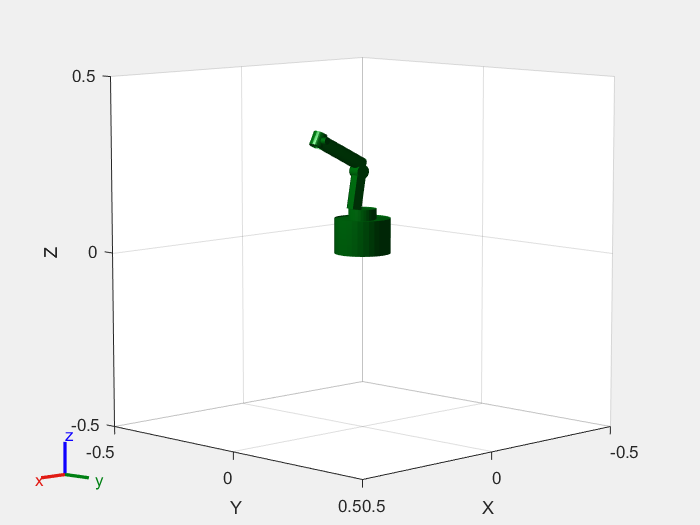

% Visualize motion on the entire robot
for i = 1:length(t)
    %show(robot, joint_trajectory(:, i), "PreservePlot", false);
    show(robot, joint_trajectory(:, i), "Collisions", "on", "Frames", "off");
    drawnow;
end

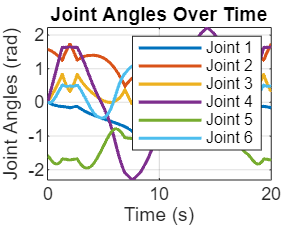


% Plot joint angles over time
figure;
plot(t, joint_trajectory', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Joint Angles (rad)');
title('Joint Angles Over Time');
legend('Joint 1', 'Joint 2', 'Joint 3', 'Joint 4', 'Joint 5', 'Joint 6');
grid on;

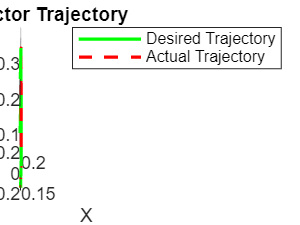


% Compute end-effector trajectory


for k = 1:length(t)
    Q_k = double(subs(Q_t, joint_angles, joint_trajectory(:, k)));
    end_effector_positions(:, k) = Q_k;
end



figure;
plot3(cartesian_traj(1, :), cartesian_traj(2, :), cartesian_traj(3, :), 'g-', 'LineWidth', 1.5);
hold on;
plot3(end_effector_positions(1, :), end_effector_positions(2, :), end_effector_positions(3, :), 'r--', 'LineWidth', 1.5);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('End-Effector Trajectory');
legend('Desired Trajectory', 'Actual Trajectory');
grid on;
hold off;

% Connect to CoppeliaSim (connets the 2 softwares)
%define host and port
%
host = '127.0.0.1'; %means they are on the same PC
port = 23000;
client = RemoteAPIClient();
sim = client.require('sim');
fprintf('Connection to CoppeliaSim is successful.\n');

Connection to CoppeliaSim is successful.



% Providing MATLAB the name of the parts of the robot (defined in Coppelia)
Name_joints = {'/Mirobot/joint1', '/Mirobot/joint2', '/Mirobot/joint3', '/Mirobot/joint4', '/Mirobot/joint5', '/Mirobot/joint6'};
Handles_joints = zeros(length(Name_joints), 1);

for i = 1:length(Name_joints)
    Handles_joints(i) = sim.getObject(Name_joints{i});
end

%activitang the simulation on Coppelia
myObj = Mirobot_Matlab; 
s = myObj.Mirobotconnect(3); %connect to COM3 for example

%SIMULATION ON MATLAB and COPPELIA
sim.startSimulation();
pause(5);
joint_trajectory_modified = (joint_trajectory - homeconfig)*(-1);
figure;
%Sending simulation to Coppelia sim:
for i = 1:length(t)
    currentConfigCoppelia = joint_trajectory_modified(1:6,i); % Get joint positions
    currentConfig = joint_trajectory(1:6,i);
    % myObj.go_to_axis(s, rad2deg(currentConfigCoppelia(1)), rad2deg(currentConfigCoppelia(2)), rad2deg(currentConfigCoppelia(3)), rad2deg(currentConfigCoppelia(4)), rad2deg(currentConfigCoppelia(5)), rad2deg(currentConfigCoppelia(6)));
    % show(robot, currentConfig, "Collisions", "on", "Frames", "off");
    % drawnow;
    % Sending the same to CoppeliaSim
    pause(0.05);
    for j = 1:length(Name_joints)
        sim.setJointTargetPosition(Handles_joints(j), currentConfigCoppelia(j));
    end
 
end

%STOP this simulation to do not overlap with the next one
sim.stopSimulation();
pause(1);
